# Getting Started with StiffMa Toolbox

## Description

StiffMa: Fast finite element STIFFness MAtrix generation on MATLAB

The finite element method (FEM) is a well established numerical technique for solving partial differential equations (PDEs) in a wide range of complex science and engineering applications. This method has two costly operation that are the construction of global matrices and vectors to form the system of linear or nonlinear equations (assemblage), and their solution (solver). Many efforts have been directed to accelerate the solver. However, the assembly stage has been less investigated although it may represent a serious bottleneck in iterative processes such as non-linear and time-dependent phenomena, and in optimization procedures involving FEM with unstructured meshes. Thus, a fast technique for the global FEM matrices construction is proposed herein by using parallel computing on graphics processing units (GPUs). 

## System Requirements

The StiffMa toolbox requires MATLAB and its Parallel Computing Toolbox (PCT). Moreover, a system with at least a GPU with compute capability 3.0 or greater. 

## Features

This work focuses on matrices that arise by solving elliptic PDEs by FEM, what is commonly known as stiffness matrix. For performance tests, a scalar problem typically represented by the thermal conduction phenomenon and a vector problem represented by the structural elasticity are considered in a three-dimensional (3D) domain. Unstructured meshes with 8-node hexahedral elements are used to discretize the domain. The MATLAB Parallel Computing Toolbox (PCT) is used to program the CUDA code. The stiffness matrix are built with three GPU kernels that are:

- the indices computation, 

- the numerical integration, and 

- the global assembly. 

Symmetry and adequate data precision are used to save memory and runtime. This proposed methodology allows generating global stiffness matrices from meshes with more than 16.3 millions elements in less than 3 seconds for the scalar problem and up to 3.1 millions for the vector one in 6 seconds using an Nvidia Tesla V100 GPU with 16 GB of memory. Large speedups are obtained compared with a non-optimized CPU code.

## Examples

Several example files are listed below:

First, add the folder containig the whole StiffMa code and its subfolders to search path

addpath(genpath(pwd));

### Execute the non-optimized StiffMa code on the CPU

- Scalar problem

runScalarOnCPU;

	Mesh created successfully with 1000 Hex8 elements and 1331 nodes!


Elapsed time for building K on serial CPU: 0.150820
Elapsed time for building tril(K) on serial CPU: 0.348089


- Vector problem

runVectorOnCPU;


The mesh was created successfully with 1000 Hex8 elements and 1331 nodes!

Elapsed time for building K on serial CPU: 0.591341
Elapsed time for building tril(K) on serial CPU: 3.123472


### Execute the StiffMa code on the GPU

- Scalar problem

if gpuDeviceCount > 0
runScalarOnGPU;
else
    disp('Your system does not have any GPU device.')
end

Your system does not have any GPU device.


- Vector problem

if gpuDeviceCount > 0
runVectorOnGPU;
else
    disp('Your system does not have any GPU device.')
end

Your system does not have any GPU device.


### Play with parameters

- Scalar problem on the CPU

edit runScalarOnCPU.m
type runScalarOnCPU.m

% Runs the whole assembly scalar code on the CPU
%
% This script is used to generate the global stiffness matrix K for the VECTOT
% problem (linear static elasticiy).
%
%   For more information, see the StiffMa web site.
%
%   Written by Francisco Javier Ramirez-Gil, fjramireg@gmail.com
%   Universidad Nacional de Colombia - Medellin
%   Created:  28/01/2020. Version: 1.4

%% Add some common paths
addpath('../Common');
addpath('../Utils');

%% Mesh generation
dxn = 1;            % For vector 3 (UX, UY, UZ). For scalar 1 (Temp)
nelx = 10;          % Number of elements on X-direction
nely = 10;          % Number of elements on Y-direction
nelz = 10;          % Number of elements on Z-direction
dTE = 'uint32';     % Data precision for "elements" ['uint32', 'uint64']
dTN = 'double';     % Data precision for "nodes" ['single' or 'double']
[Mesh.elements, Mesh.nodes] = CreateMesh2(nelx,nely,nelz,dTE,dTN);
[nel, nxe] = size

runScalarOnCPU;

	Mesh created successfully with 1000 Hex8 elements and 1331 nodes!


Elapsed time for building K on serial CPU: 0.299361
Elapsed time for building tril(K) on serial CPU: 0.653125


- Plot the mesh (w/o numbering)

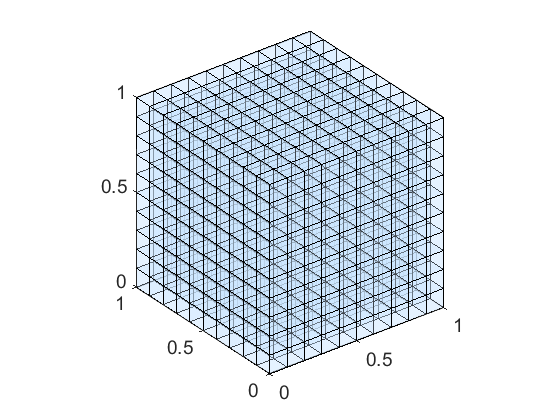

PlotMesh(Mesh.elements,Mesh.nodes,0,0);

- Plot the sparse stiffness matrix generated (symmetric case)

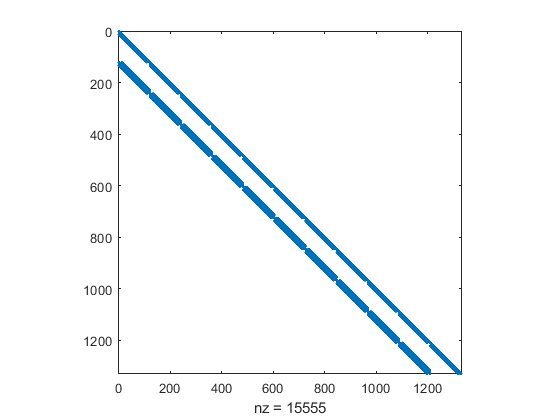

spy(K_s)